Given the initial hidden state z0 = 0, we have the sequence:

z_{i+1} = a*z_{i} + b

a = 0.5, and the noise b randomly drawn from the Gaussian distribution (0,1)

**STEP 1: Generate 1000 hidden states z's, with initial hidden state z0**

clear
clc

z0 = 0;
a = 0.5;
b = normrnd(0,1,[1,1000]);
num_samples = 1000;

z = zeros(1, num_samples) ;
z(1) = a*z0 + b(1);

for i=2:num_samples
    z(i) = a*z(i-1) + b(i);
end

z_prev = zeros(1, num_samples);
z_prev(1) = z0;
for i=2:num_samples
    z_prev(i) = z(i-1);
end

Define the observation x's give the hidden states z's, namely x_{i} is drawn from the Gaussian distribution (z_{i},1)

**STEP 2: Generate 1000 observations x's, given the 1000 hidden states z's**

(

Given the generated x's and z's, we seek to find y's such that

y_{i} = x_{i} - ( alpha*z_{i} + beta ) 

with mean(y) = minimize \sum_{i=1}^{num_samples} ||x_{i} - ( alpha*z_{i} + beta ) || ^ 2 over alpha and beta.

**STEP 3: Find the optimal parameters alpha and beta using Least-Squares Fitting**

Z = ones(num_samples, 2);
Z(:,2) = z';
% calculate alpha, beta
ab = (Z' * Z) \ (Z' * x');

% calculate estimate x_hat = alpha*z + beta
x_hat = (Z*ab)';
least_square_error = sum((x_hat - x) .^ 2);
disp("least_square_error ")

least_square_error 


disp(least_square_error)

   1.0521e+03



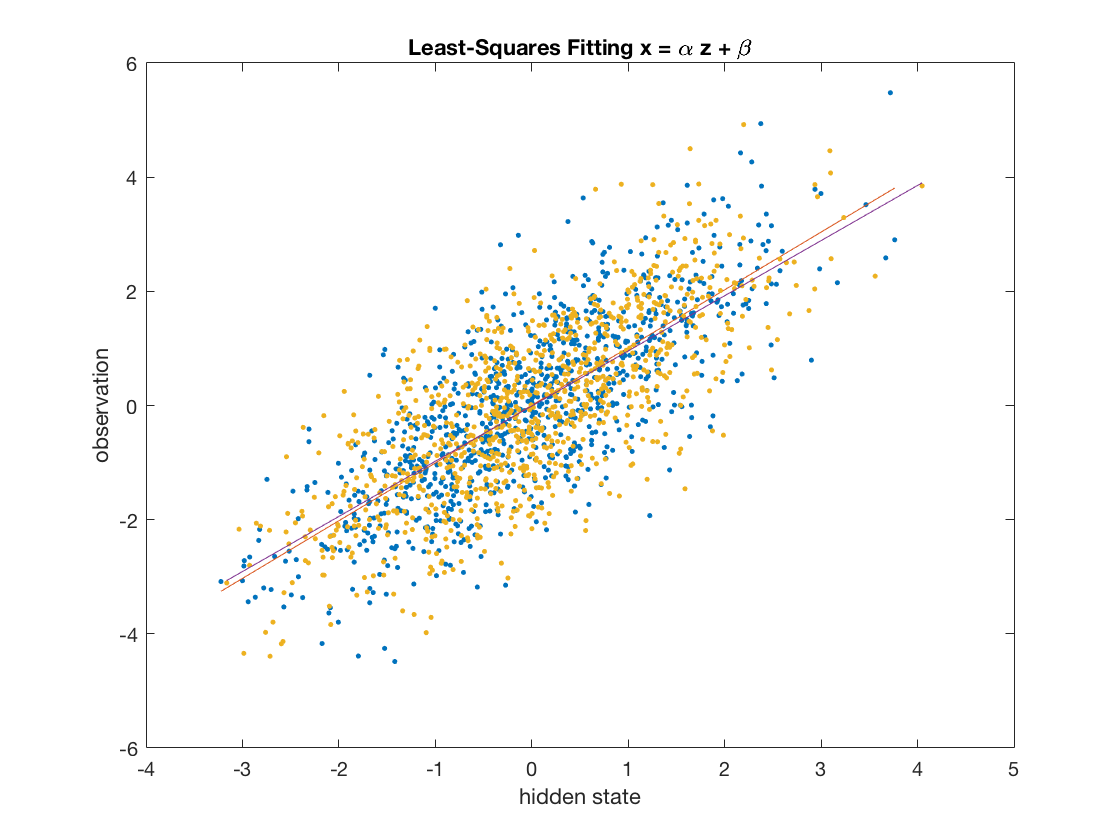

% visualize the original data 
figure(1)
plot(z, x,'.')
title("Least-Squares Fitting x = \alpha z + \beta")
xlabel('hidden state')
ylabel('observation')
hold on

% Plot the best fit line.
plot(z, x_hat)

ab

ab =    -0.0098
    0.9663


**STEP 4: Find the optimal parameters gamma and delta using Least-Squares Fitting**

Z_PREV = ones(num_samples, 2);
Z_PREV(:,2) = z_prev';
% calculate gamma, delta
gd = (Z_PREV' * Z_PREV) \ (Z_PREV' * z');

% calculate estimate z_hat = gamma*z' + delta
z_hat = (Z_PREV*gd)';
least_square_error = sum((z_hat - z) .^ 2);
disp("least_square_error ")

least_square_error 


disp(least_square_error)

   1.0269e+03



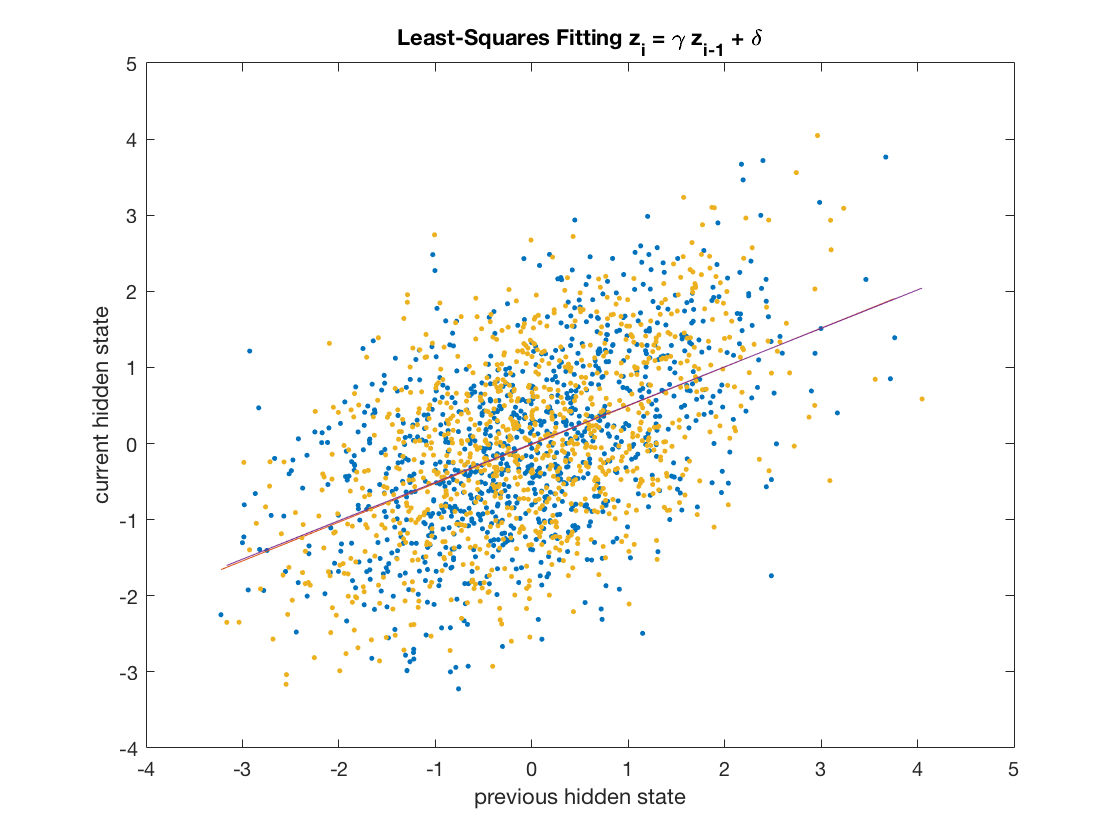

% visualize the original data 
figure(2)
plot(z_prev, z,'.')
title("Least-Squares Fitting z_i = \gamma z_{i-1} + \delta")
xlabel('previous hidden state')
ylabel('current hidden state')
hold on

% Plot the best fit line.
plot(z_prev, z_hat)

gd

gd =    -0.0026
    0.5054


**STEP 4: Calculate y**

y = x - x_hat;

saveas(figure(1),'sample(x,z).png')